clear all;
clc;

Station_01_far_dunham = readtable('Benchmark_Data_dunham\farst-120dp075.txt');

Station_02_far_dunham = readtable('Benchmark_Data_dunham\farst-120dp000.txt');

Station_03_far_dunham = readtable('Benchmark_Data_dunham\farst000dp000.txt');

Station_04_far_dunham = readtable('Benchmark_Data_dunham\farst120dp000.txt');

Station_05_far_dunham = readtable('Benchmark_Data_dunham\farst120dp075.txt');

Station_01_near_dunham = readtable('Benchmark_Data_dunham\nearst-120dp075.txt');

Station_02_near_dunham = readtable('Benchmark_Data_dunham\nearst-120dp000.txt');

Station_03_near_dunham = readtable('Benchmark_Data_dunham\nearst000dp000.txt');

Station_04_near_dunham = readtable('Benchmark_Data_dunham\nearst120dp000.txt');

Station_05_near_dunham = readtable('Benchmark_Data_dunham\nearst120dp075.txt');


Station_01_TBSBIEM = readtable('dats\out01.dat');
Station_02_TBSBIEM = readtable('dats\out02.dat');
Station_03_TBSBIEM = readtable('dats\out03.dat');
Station_04_TBSBIEM = readtable('dats\out04.dat');
Station_05_TBSBIEM = readtable('dats\out05.dat');

tit = 'Station01'

far_liu = 'Station_01_far_liu'

near_liu = 'Station_01_near_liu'

far_dunham = 'Station_01_far_dunham'

near_dunham = 'Station_01_near_dunham'

TBSBIEM = 'Station_01_TBSBIEM'

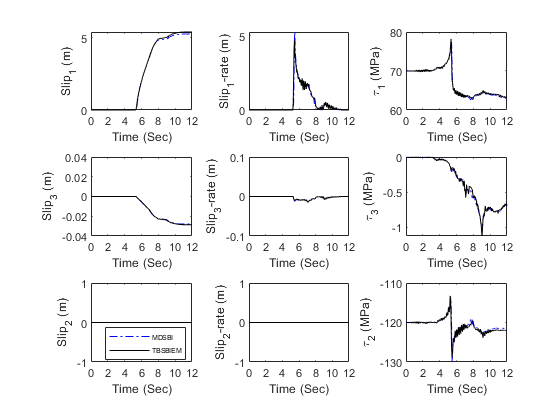

tit = 'Station02'

far_liu = 'Station_02_far_liu'

near_liu = 'Station_02_near_liu'

far_dunham = 'Station_02_far_dunham'

near_dunham = 'Station_02_near_dunham'

TBSBIEM = 'Station_02_TBSBIEM'

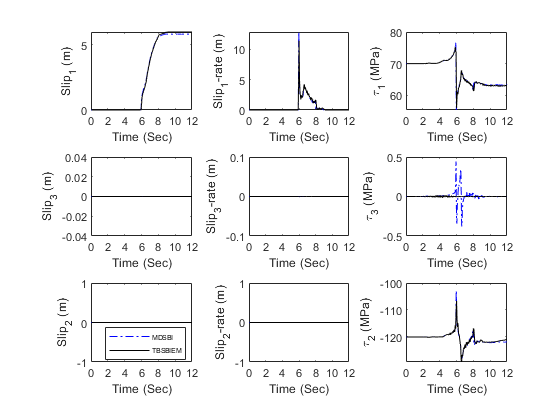

tit = 'Station03'

far_liu = 'Station_03_far_liu'

near_liu = 'Station_03_near_liu'

far_dunham = 'Station_03_far_dunham'

near_dunham = 'Station_03_near_dunham'

TBSBIEM = 'Station_03_TBSBIEM'

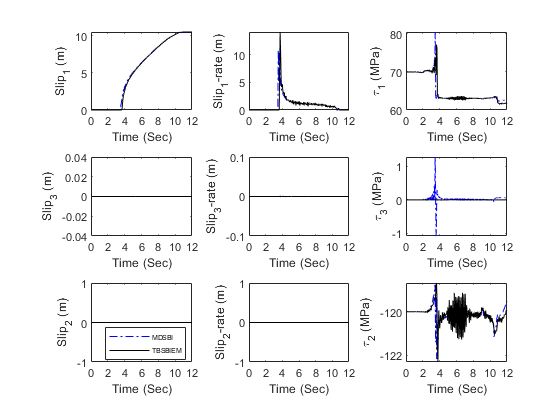

tit = 'Station04'

far_liu = 'Station_04_far_liu'

near_liu = 'Station_04_near_liu'

far_dunham = 'Station_04_far_dunham'

near_dunham = 'Station_04_near_dunham'

TBSBIEM = 'Station_04_TBSBIEM'

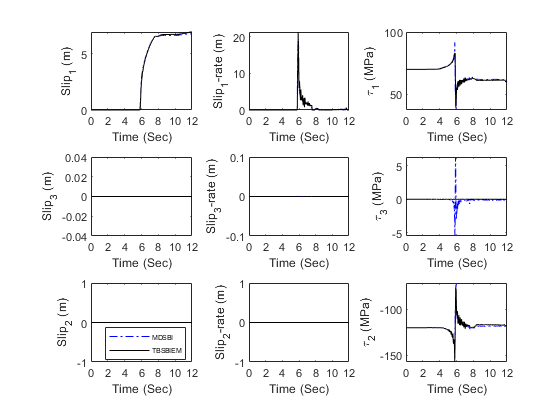

tit = 'Station05'

far_liu = 'Station_05_far_liu'

near_liu = 'Station_05_near_liu'

far_dunham = 'Station_05_far_dunham'

near_dunham = 'Station_05_near_dunham'

TBSBIEM = 'Station_05_TBSBIEM'

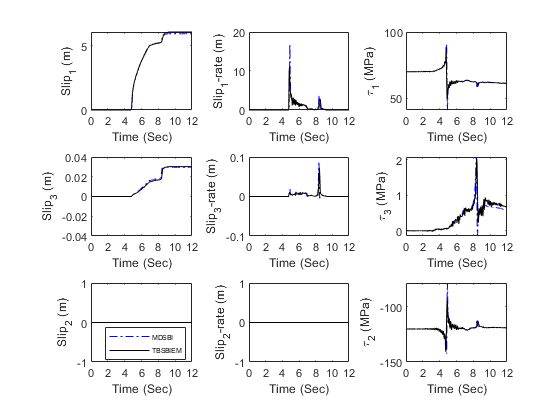


for i=1:5
%   Mainplot i
    figure(i);
    tit = ['Station' num2str(i,'%.2i')]
%     sgtitle(tit)
    far_liu = ['Station_' num2str(i,'%.2i') '_far_liu']
    near_liu = ['Station_' num2str(i,'%.2i') '_near_liu'] 
    far_dunham = ['Station_' num2str(i,'%.2i') '_far_dunham']
    near_dunham = ['Station_' num2str(i,'%.2i') '_near_dunham'] 
    TBSBIEM = ['Station_' num2str(i,'%.2i') '_TBSBIEM']
%   Subplot 1
    subplot(3,3,1)    
%     plot(eval(far_liu).t, (eval(far_liu).h_disp-eval(near_liu).h_disp),'--r',"LineWidth",0.21);
%     hold on
    plot(eval(far_dunham).t, (eval(far_dunham).h_disp-eval(near_dunham).h_disp),'-.b',"LineWidth",0.21);
    hold on
    plot(eval(TBSBIEM).Var1,(eval(TBSBIEM).Var2),'k-',"LineWidth",0.21,'MarkerSize',0.21);    
    xlim([0 12])
    xticks(0:2:12)
    xlabel('Time (Sec)')
    ylabel('Slip_1 (m)')
%     legend('liu','TBSBIEM','Location',"northwest",'Orientation',"vertical",'FontSize',5)
    hold off
%   Subplot 2
    subplot(3,3,2)
%     plot(eval(far_liu).t,(eval(far_liu).h_vel-eval(near_liu).h_vel),'--r',"LineWidth",0.21);
%     hold on
    plot(eval(far_dunham).t,(eval(far_dunham).h_vel-eval(near_dunham).h_vel),'-.b',"LineWidth",0.21);
    hold on
    plot(eval(TBSBIEM).Var1,(eval(TBSBIEM).Var3),'k-',"LineWidth",0.21,'MarkerSize',0.21);
    xlim([0 12])
    xticks(0:2:12)
    xlabel('Time (Sec)')
    ylabel('Slip_1-rate (m)')
    hold off
%   Subplot 3    
    subplot(3,3,3) % (Station_A_far.h_stress+Station_A_near.h_stress)/2
%     plot(eval(far_liu).t,(eval(far_liu).h_stress+eval(near_liu).h_stress)/2,'--r',"LineWidth",0.21);
%     hold on
    plot(eval(far_dunham).t,(eval(far_dunham).h_stress+eval(near_dunham).h_stress)/2,'-.b',"LineWidth",0.21);
    hold on
    plot(eval(TBSBIEM).Var1,eval(TBSBIEM).Var4,'k-',"LineWidth",0.21,'MarkerSize',0.21);
    xlim([0 12])
    xticks(0:2:12)
    xlabel('Time (Sec)')
    ylabel('\tau_1 (MPa)')
    hold off
%   Subplot 4    
    subplot(3,3,4)    
%     plot(eval(far_liu).t, (eval(far_liu).v_disp-eval(near_liu).v_disp),'--r',"LineWidth",0.21);
%     hold on
    plot(eval(far_dunham).t, (eval(far_dunham).v_disp-eval(near_dunham).v_disp),'-.b',"LineWidth",0.21);
    hold on
    plot(eval(TBSBIEM).Var1,(eval(TBSBIEM).Var5),'k-',"LineWidth",0.21,'MarkerSize',0.21);
    xlim([0 12])
    ylim([-0.04 0.04])
    xticks(0:2:12)
    xlabel('Time (Sec)')
    ylabel('Slip_3 (m)')
%     legend('liu','TBSBIEM','Location',"northwest",'Orientation',"vertical",'FontSize',5)
    hold off
%   Subplot 2
    subplot(3,3,5)
%     plot(eval(far_liu).t,(eval(far_liu).v_vel-eval(near_liu).v_vel),'--r',"LineWidth",0.21);
%     hold on
    plot(eval(far_dunham).t,(eval(far_dunham).v_vel-eval(near_dunham).v_vel),'-.b',"LineWidth",0.21);
    hold on
    plot(eval(TBSBIEM).Var1,(eval(TBSBIEM).Var6),'k-',"LineWidth",0.21,'MarkerSize',0.21);
    xlim([0 12])
    ylim([-0.1 0.1])
    xticks(0:2:12)
    xlabel('Time (Sec)')
    ylabel('Slip_3-rate (m)')
    hold off
%   Subplot 3    
    subplot(3,3,6) % (Station_A_far.h_stress+Station_A_near.h_stress)/2
%     plot(eval(far_liu).t,(eval(far_liu).v_stress+eval(near_liu).v_stress)/2,'--r',"LineWidth",0.21);
%     hold on
    plot(eval(far_dunham).t,(eval(far_dunham).v_stress+eval(near_dunham).v_stress)/2,'-.b',"LineWidth",0.21);
    hold on
    plot(eval(TBSBIEM).Var1,eval(TBSBIEM).Var7,'k-',"LineWidth",0.21,'MarkerSize',0.21);
    xlim([0 12])
    xticks(0:2:12)
    xlabel('Time (Sec)')
    ylabel('\tau_3 (MPa)')
    hold off
%   Subplot 7    
    subplot(3,3,7)    
%     plot(eval(far_liu).t, (eval(far_liu).n_disp-eval(near_liu).n_disp),'--r',"LineWidth",0.21);
%     hold on
    plot(eval(far_dunham).t, (eval(far_dunham).n_disp-eval(near_dunham).n_disp),'-.b',"LineWidth",0.21);
    hold on
    plot(eval(TBSBIEM).Var1,(eval(TBSBIEM).Var8),'k-',"LineWidth",0.21,'MarkerSize',0.21);
    xlim([0 12])
    xticks(0:2:12)
    xlabel('Time (Sec)')
    ylabel('Slip_2 (m)')
    
    hold off
    legend('MDSBI','TBSBIEM','Orientation',"vertical",'FontSize',5,'Position',[0.2 0.1425 0.12 0.08])  
% Subplot 8
    subplot(3,3,8)
%     plot(eval(far_liu).t,(eval(far_liu).n_vel-eval(near_liu).n_vel),'--r',"LineWidth",0.21);
%     hold on
    plot(eval(far_dunham).t,(eval(far_dunham).n_vel-eval(near_dunham).n_vel),'-.b',"LineWidth",0.21);
    hold on
    plot(eval(TBSBIEM).Var1,(eval(TBSBIEM).Var9),'k-',"LineWidth",0.21,'MarkerSize',0.21);
    xlim([0 12])
    xticks(0:2:12)
    xlabel('Time (Sec)')
    ylabel('Slip_2-rate (m)')
    hold off
%   Subplot 9    
    subplot(3,3,9) % (Station_A_far.h_stress+Station_A_near.h_stress)/2
%     plot(eval(far_liu).t,(eval(far_liu).n_stress+eval(near_liu).n_stress)/2,'--r',"LineWidth",0.21);
%     hold on
    plot(eval(far_dunham).t,(eval(far_dunham).n_stress+eval(near_dunham).n_stress)/2,'-.b',"LineWidth",0.21);
    hold on
    plot(eval(TBSBIEM).Var1,eval(TBSBIEM).Var10,'k-',"LineWidth",0.21,'MarkerSize',0.21);
    xlim([0 12])
    xticks(0:2:12)
    xlabel('Time (Sec)')
    ylabel('\tau_2 (MPa)')
    hold off
    saveas(figure(i),['Figs\TPV6_' tit '.jpeg']) 
    saveas(figure(i),['Figs\TPV6_',tit,'.eps'],'epsc')    
end